## POC 3b

As the setup of POC No. 3 went wrong and I dont want to fix it, here a new version..

### Basic setup

data_file       = '../data/v3/230920_16042025.csv';
meta_file       = '../data/v3/230920_16042025.json';
output_path     = 'output/ddindd';
addpath("ddindd/");

%%% READ INPUTS
try
    data        = readtable( data_file, Delimiter = ',');
catch e
    error("[ERROR][data reader] " + convertCharsToStrings(e.message));
end

try
    metadata    = jsondecode( fileread( meta_file ) );
catch e
    disp("[WARNING][metadata reader] " + convertCharsToStrings(e.message));
    metadata    = {};
end

%%% DDINDD
d   = ddindd(data, method = 'langmuir', metaFile = metadata, relInj = 0);

[WARNING][func fit] No matching data for round 8 and injection type Negative sample


%%%% BASIC FUNC
    %% GetInjectionType: Return injection type
    %
    % Args:
    %       i (int): injection type integer
    %
    % Result:
    %       inj_type (string): injection type string
    %
    function inj_type = GetInjectionType(i)
        switch i
            case 0
                inj_type = "Negative sample";
            case 1
                inj_type = "Positive sample";
            case 3
                inj_type = "Flush";
            case 4
                inj_type = "Urea";
            otherwise
                inj_type = "Unknown";
        end
    end

%%%% LOAD DATA FROM DDINDD
try shortFileId     = d.meta.shortFileId;   catch; shortFileId     = "NaN";                             end
try dateStr         = d.meta.dateStr;       catch; dateStr         = "0000-00-00";                      end

try injections      = d.meta.injections;    catch; injections      = [];                                end

try relInj          = d.meta.relInj;        catch; relInj          = 0;                                 end

try fitFunction     = d.meta.method;        catch; fitFunction     = {"no fit function found"};         end
try fitFunctionH    = d.meta.methodFunc;    catch; fitFunctionH    = 0;                                 end
try fitFunctionEx   = d.meta.methodEx;      catch; fitFunctionEx   = {"no ex for fit function found"};  end

try n_rounds        = d.meta.n_rounds;      catch; n_rounds        = 2;                                 end
nRoundsStr          = convertCharsToStrings(num2str(n_rounds));

try n_sensors       = d.meta.n_sensors;     catch; n_sensors        = 8;                                end

try data            = d.raw;           catch; data             = data;                             end

%%%% TABLES
drift_sp_T = cell(n_rounds, n_sensors); sp_corr_T = cell(n_rounds, n_sensors); best_a_T = cell(n_rounds, n_sensors); best_b_T = cell(n_rounds, n_sensors); rsquared_T = cell(n_rounds, n_sensors);
    for r = 1:n_rounds
        round = "round" + r;
        for s = 1:n_sensors
            sensor = "sensor" + s;
            try drift_sp_T{r, s}    = d.(round).(sensor).driftSP;   catch; drift_sp_T{r, s} = NaN;  end
            try sp_corr_T{r, s}     = d.(round).(sensor).SPcorr;    catch; sp_corr_T{r, s}  = NaN;  end
            try best_a_T{r, s}      = d.(round).(sensor).a;         catch; best_a_T{r, s}   = NaN;  end
            try best_b_T{r, s}      = d.(round).(sensor).b;         catch; best_b_T{r, s}   = NaN;  end
            try rsquared_T{r, s}    = d.(round).(sensor).Rsquared;  catch; rsquared_T{r, s} = NaN;  end
        end
    end

% styles
colmap = repmat([1 0 0; 0 0 0], d.meta.n_sensors, 1);
markermap = {'o', '+', 'square', 'x', 'diamond', '*', '^', '|', '>', '<', 'v', 'hexagram', '.'};

### Plot raw data

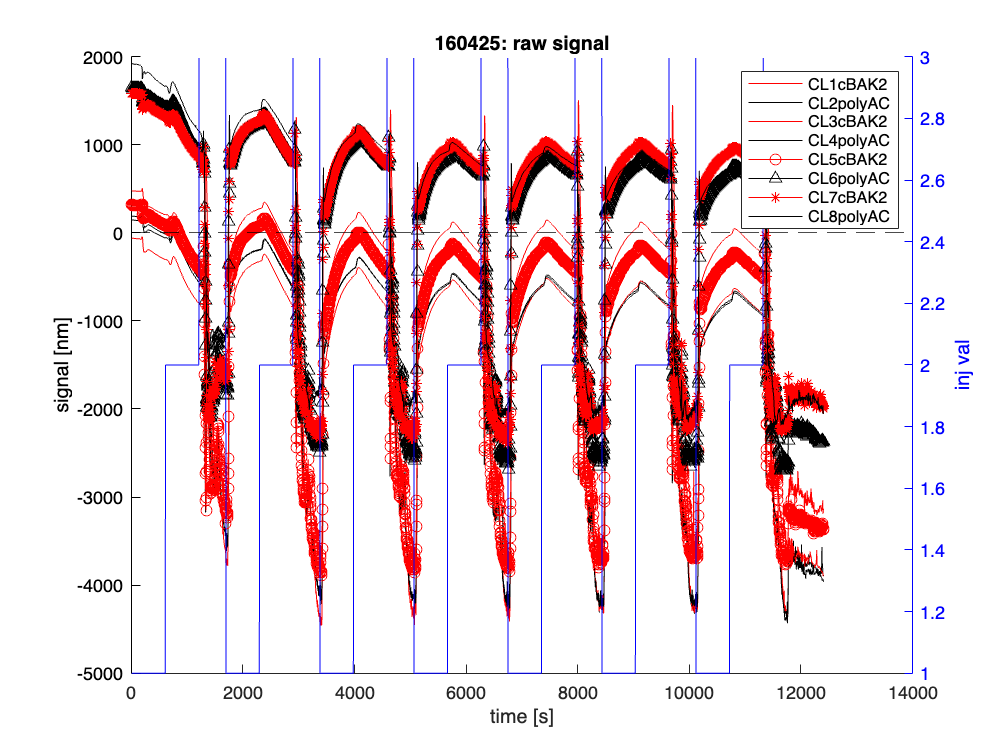

figure; hold on; colororder({'k','b'}); yyaxis left;
for i = 1:8
    plot(data.("T_s_"), data{:, i+4}, Color = colmap(i, :), LineStyle = '-', DisplayName = data.Properties.VariableNames{i+4}); 
end
ylabel("signal [nm]");
yline(0, 'k--', HandleVisibility = 'off');
yyaxis right; plot(data.("T_s_"), data{:, "Val_"}, Color = 'b', HandleVisibility = 'off');
legend(); ylabel("inj val"); xlabel("time [s]"); title(shortFileId + ": raw signal")

### Correct data w/ drift in negative sample (Buffer)

For each round (consisting of neg sample injection (0), pos sample inj (1) and urea inj (4)) set to 0 at beginning of pos sample inj.

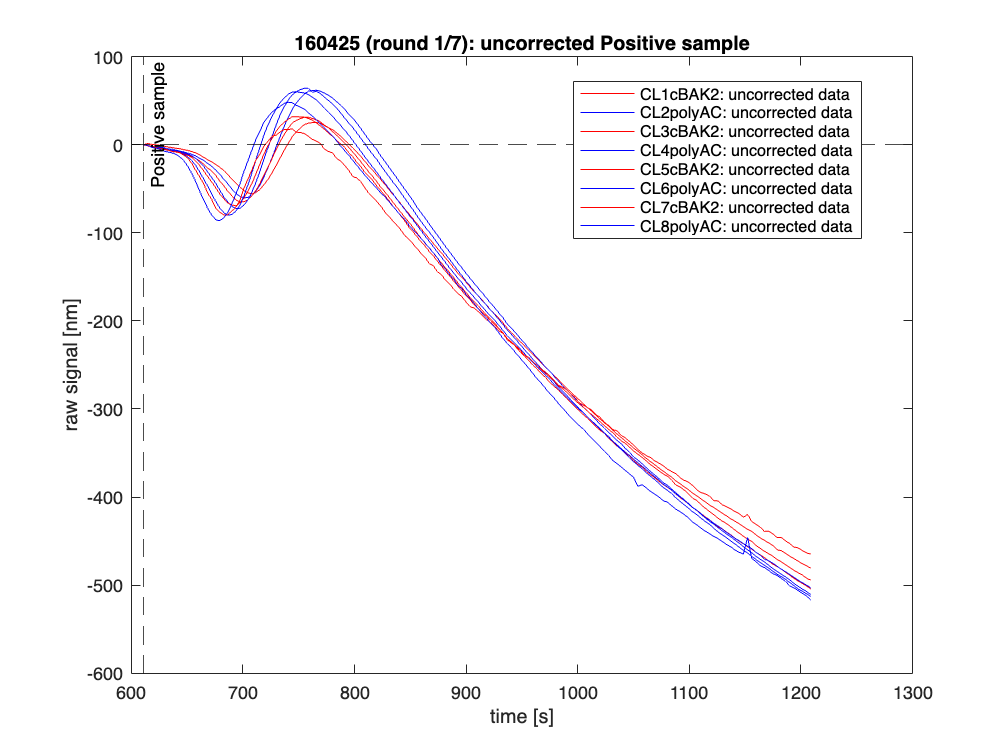

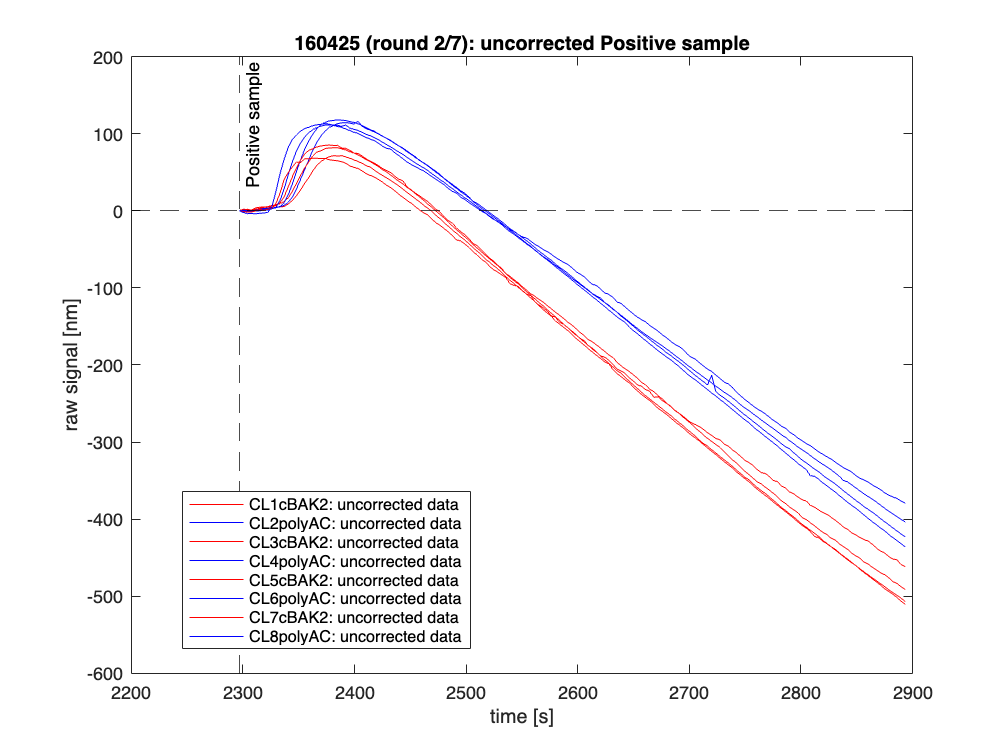

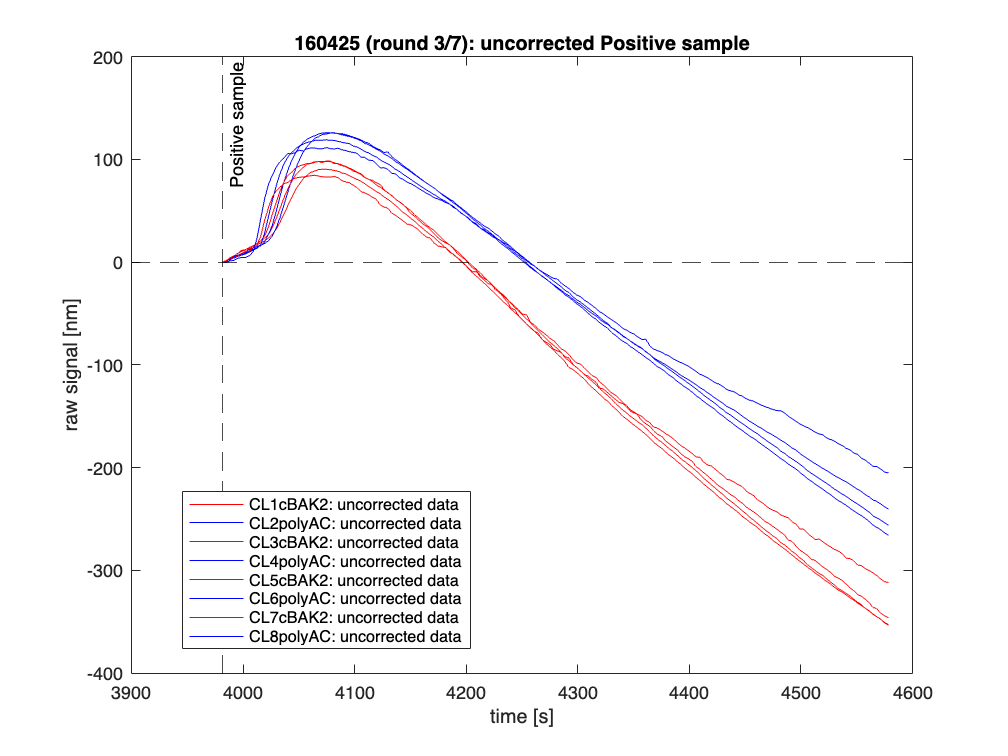

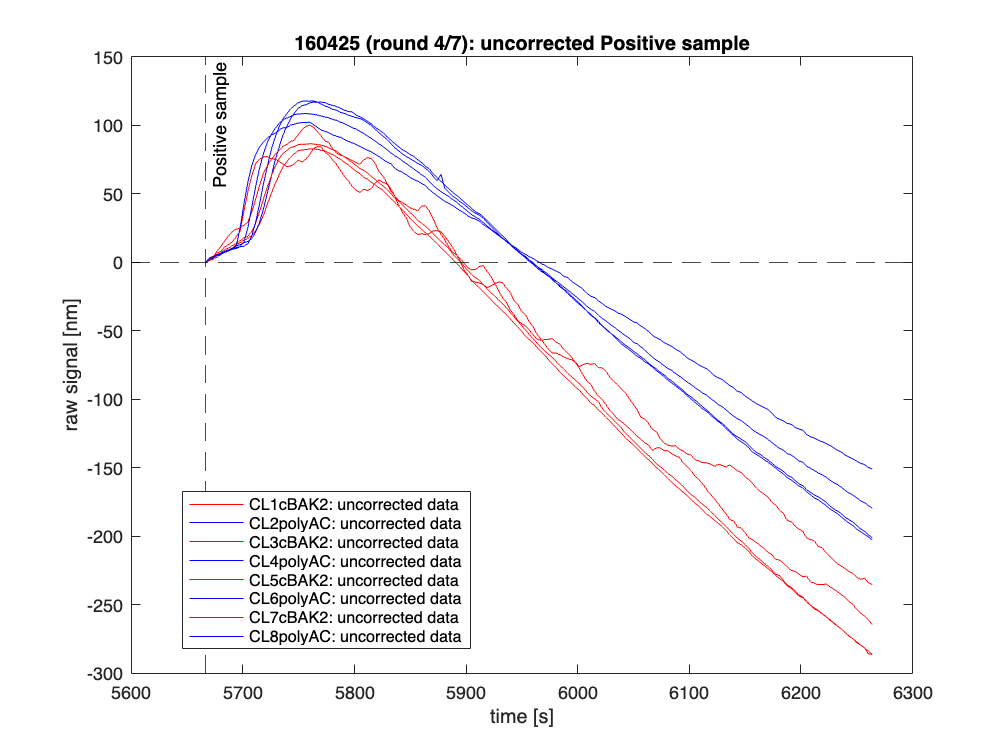

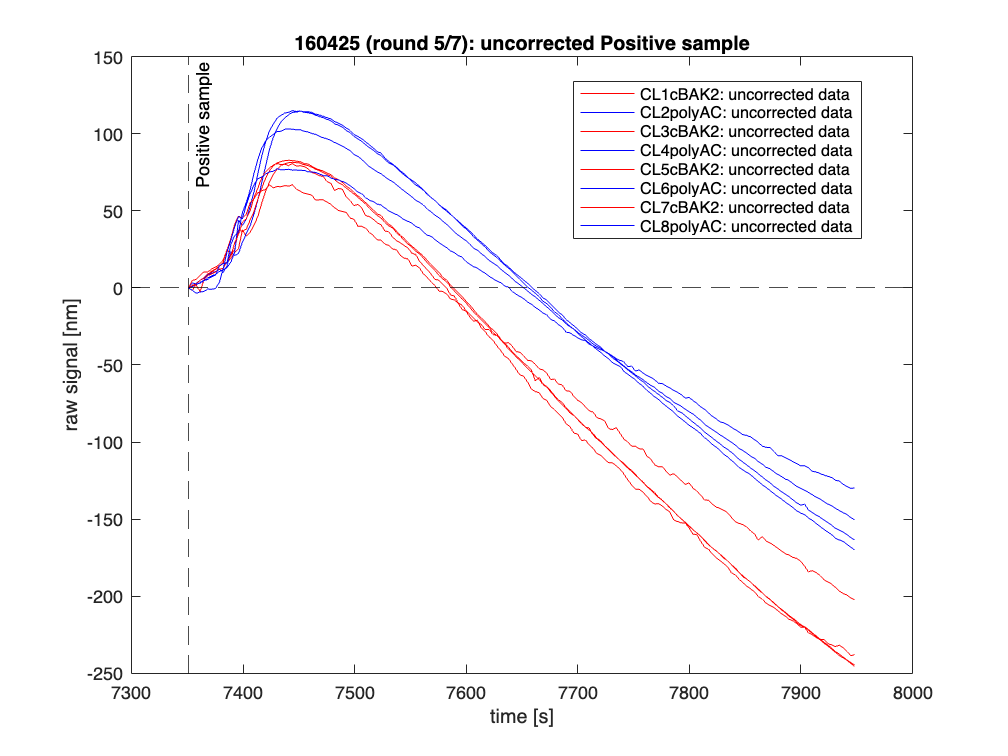

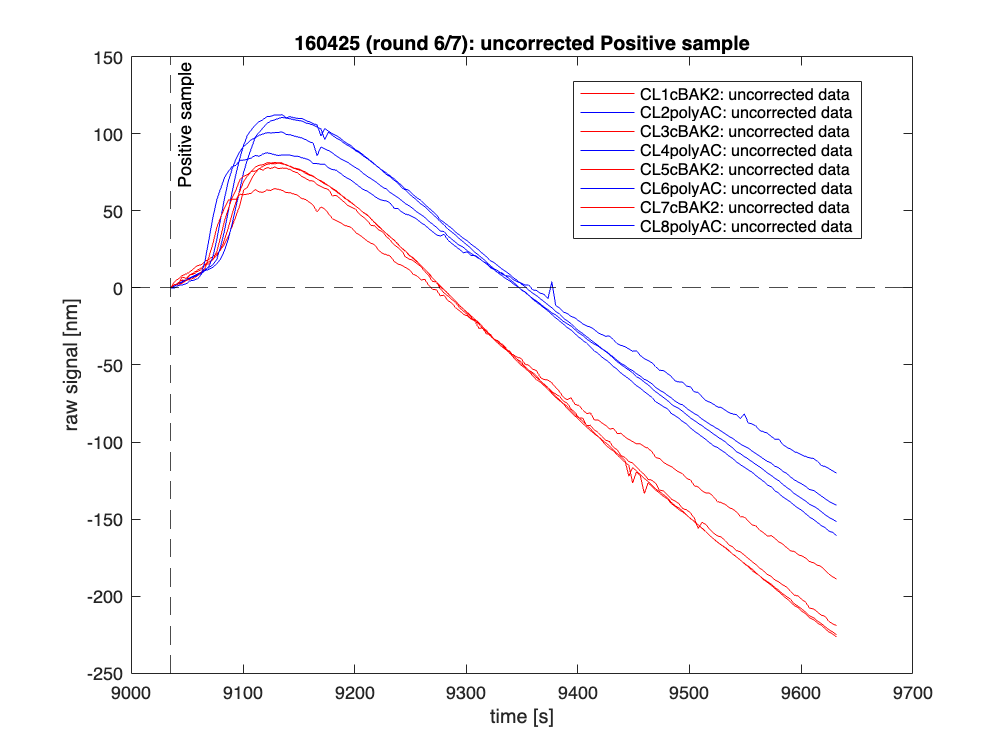

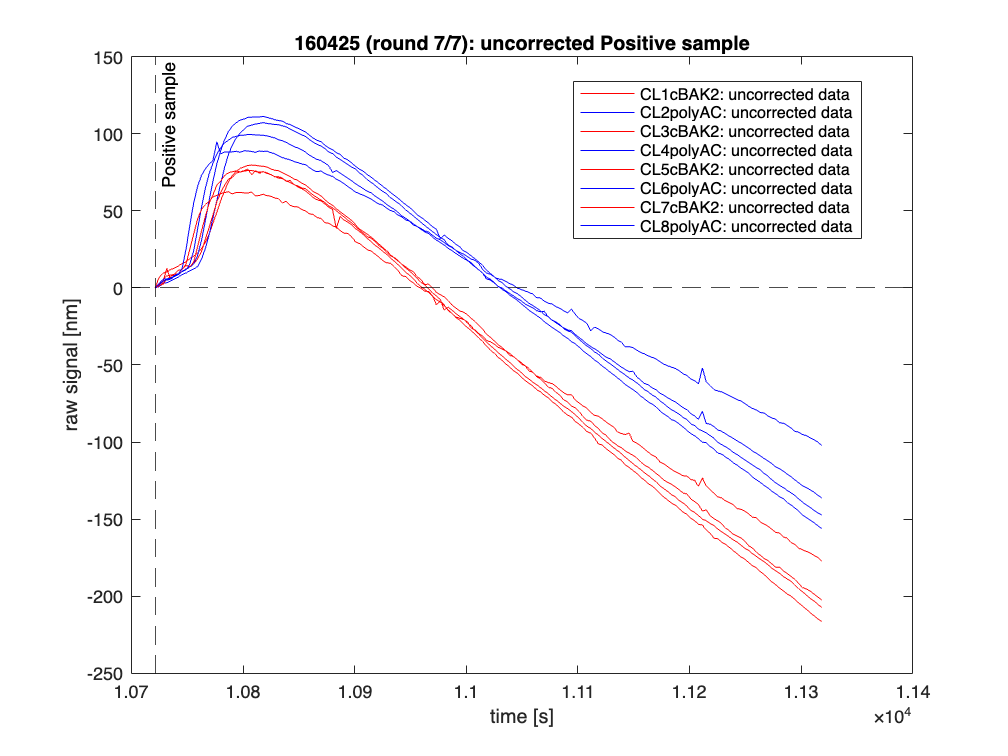

for r = 1:n_rounds
    round = "round" + r;

    clf(figure(r));             % clear figure
    H{r}        = figure(r);    % create figure for round
    fig_handles = [];           % create empty array for handles
    
    % load data
    pltData     = data(data.round == r & data.inj_type == 1, :);  
    plttgLength = height(pltData);

    for s = 1:n_sensors
        sensor      = "sensor" + s; 
        sensor_name = pltData.Properties.VariableNames{s+4};

        posStrVal   = pltData{1, s+4};

        % plot uncorr data
        h = plot(pltData{:, "T_s_"}, pltData{:, s+4} - posStrVal, Color = colmap(s, :), Marker = 'none', DisplayName = sensor_name + ": uncorrected data"); hold on;
        fig_handles = [fig_handles h];
    end

    yline(0, Color = 'k', LineStyle = '--', HandleVisibility = 'off'); % add 0 base line
    xline(pltData.T_s_(1), Color = 'k', LineStyle = '--', HandleVisibility = 'off', Label = GetInjectionType(1));

    title(shortFileId + " (round " + r + "/" + n_rounds + "): uncorrected " + GetInjectionType(1) );
    xlabel("time [s]"); ylabel("raw signal [nm]");
    legend(fig_handles, 'Location', 'best'); hold off;
end

Now lets analyze the range and std dev of the raw data

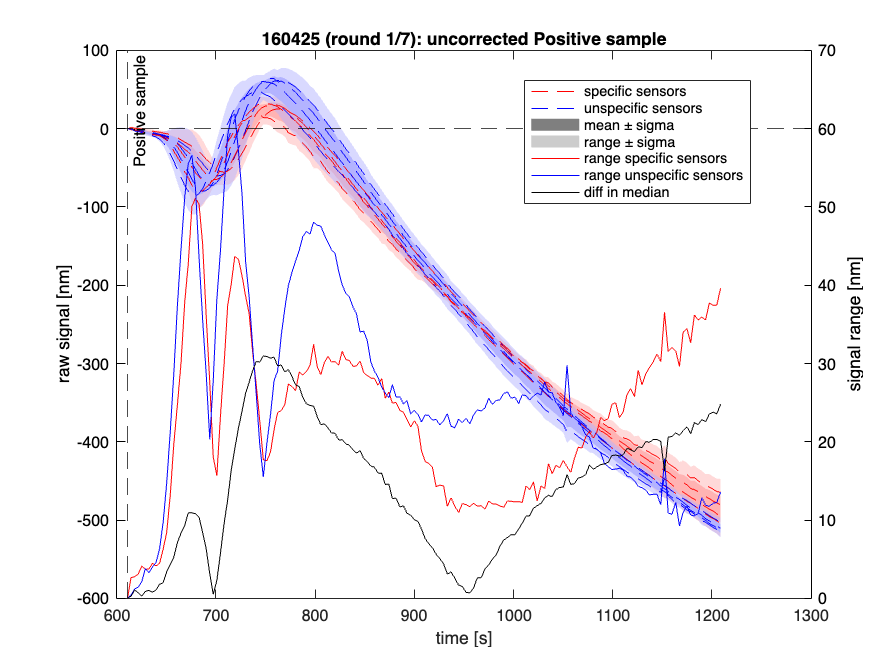

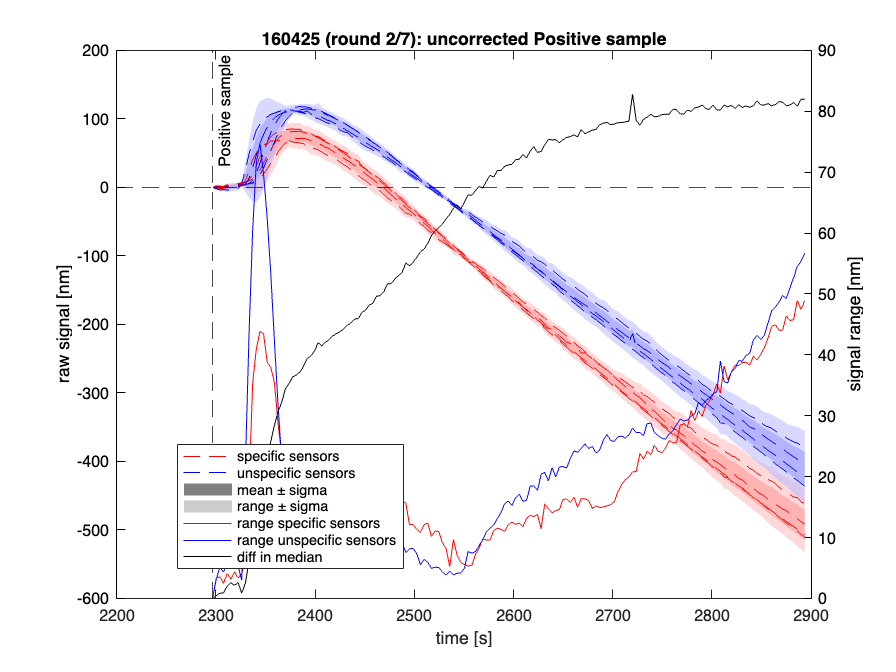

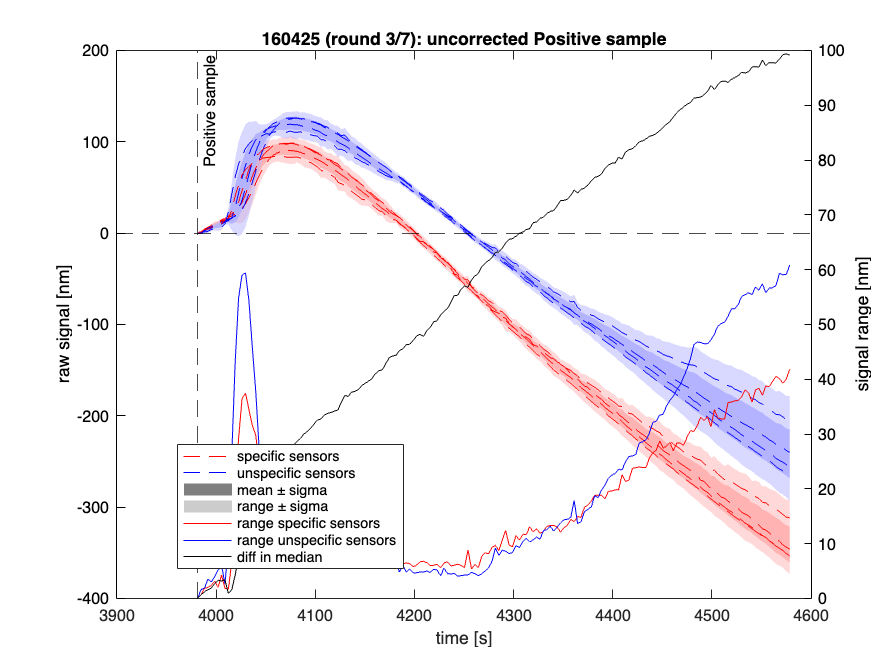

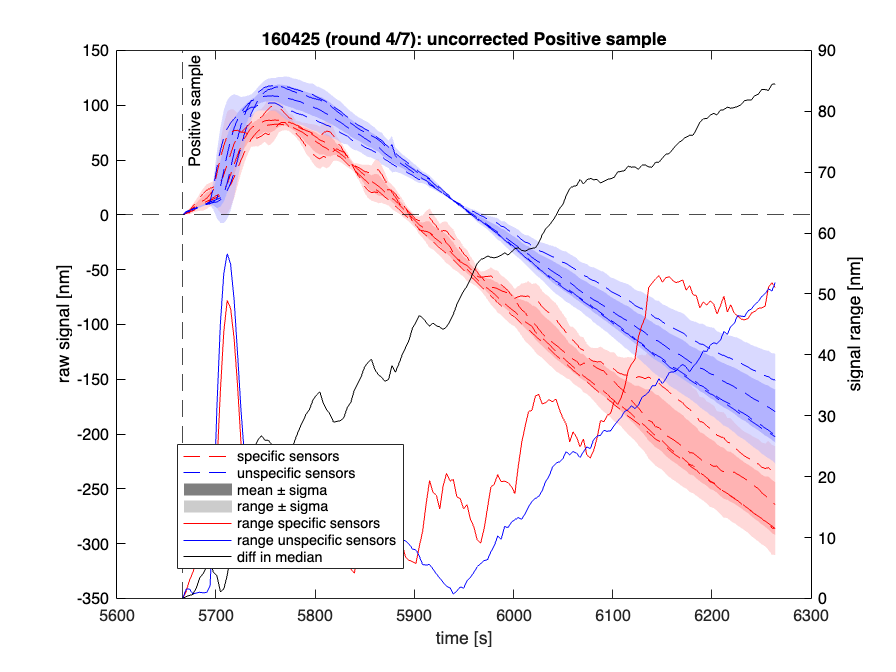

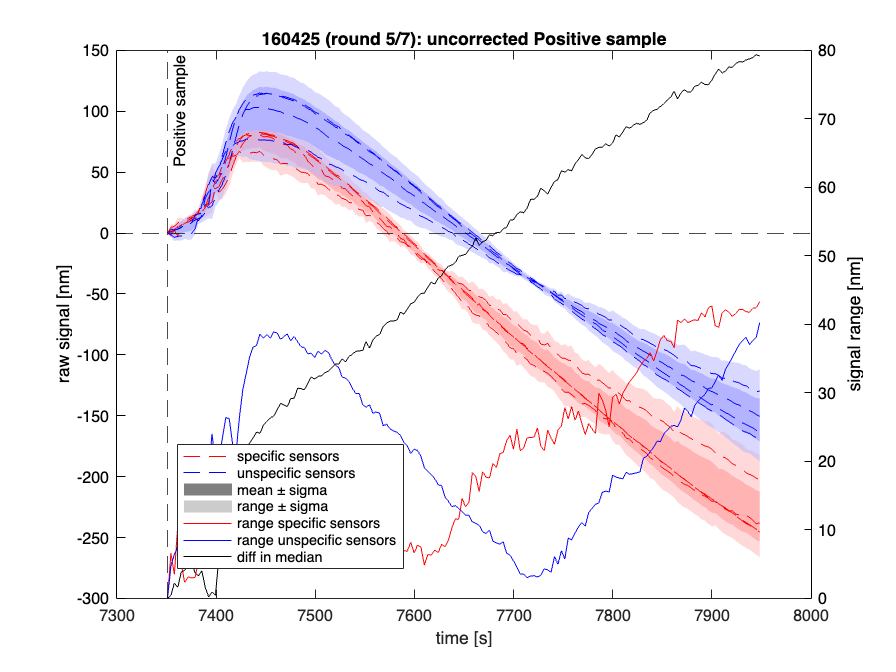

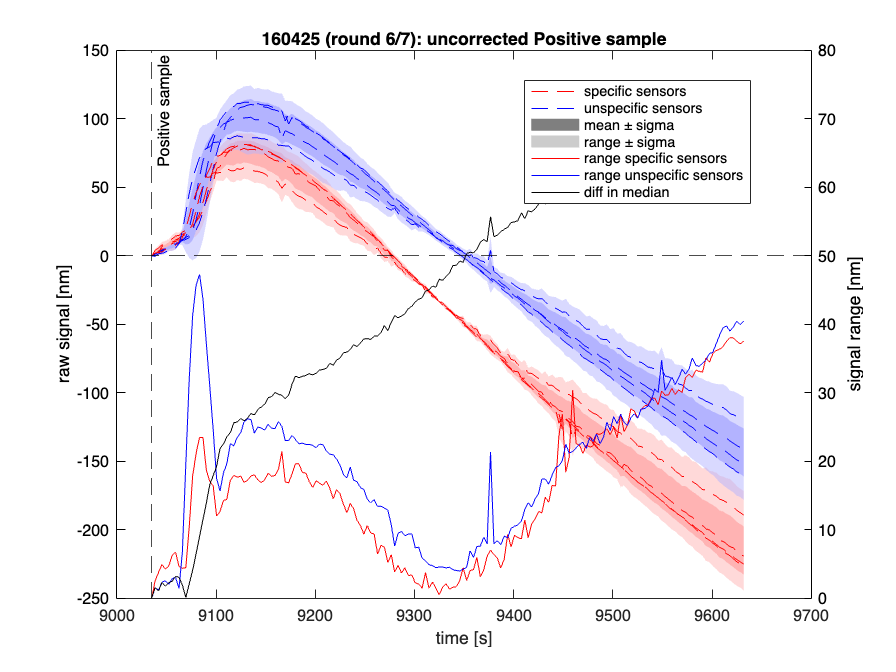

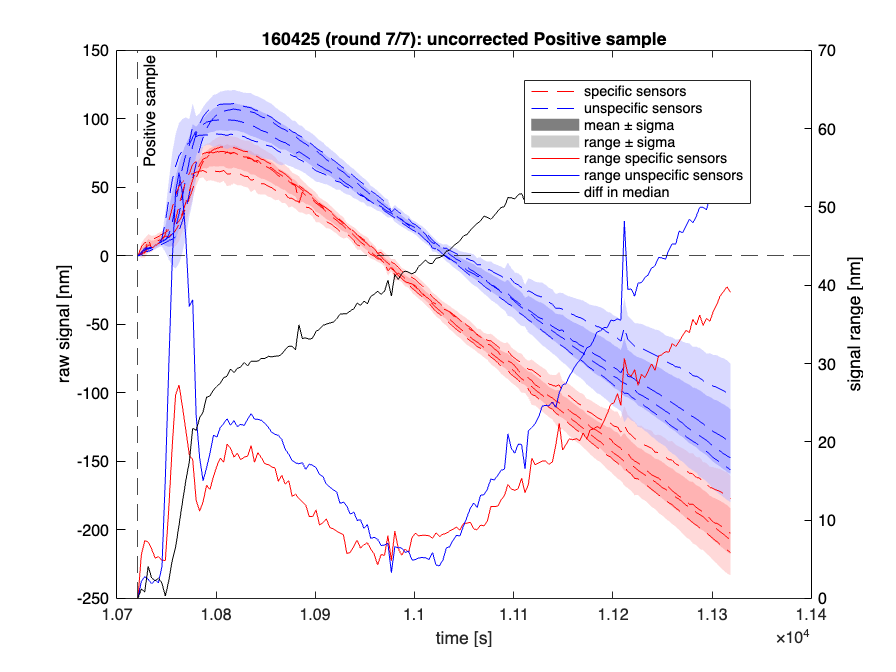

for r = 1:n_rounds
    round = "round" + r;

    clf(figure(r));             % clear figure
    H{r}        = figure(r);    % create figure for round
    fig_handles = [];           % create empty array for handles
    
    % load data
    pltData     = data(data.round == r & data.inj_type == 1, :);  
    plttgLength = height(pltData);

    colororder({'k','k'}); yyaxis left;

    sensor_groups = {[1 3 5 7], [2 4 6 8]}; sensor_groups_names = {"specific", "unspecific"}; colors_fill = [1 .7 .7; .7 .7 1];
    for g = 1:2
        sensor_idx = sensor_groups{g};
        data_group = zeros(plttgLength, numel(sensor_idx));

        for k = 1:numel(sensor_idx)
            s = sensor_idx(k);
            posStrVal = pltData{1, s+4};
            data_group(:, k) = pltData{:, s+4} - posStrVal;
        end

        y_min = min(data_group, [], 2);
        y_max = max(data_group, [], 2);
        y_std = std(data_group, 0, 2);  % std dev
        y_mean = mean(data_group, 2); % mean
        t = pltData.T_s_;

        fill([t; flipud(t)], [y_min - y_std; flipud(y_max + y_std)], colors_fill(g, :), FaceAlpha = 0.5, EdgeColor = 'none'); hold on;
        fill([t; flipud(t)], [y_mean - y_std; flipud(y_mean + y_std)], colors_fill(g, :), FaceAlpha = 1, EdgeColor = 'none');

        range_values{g} = y_max - y_min;
        std_values{g} = y_std;
        mean_values{g} = y_mean;
    end
    
    for s = 1:n_sensors
        sensor      = "sensor" + s; 
        sensor_name = pltData.Properties.VariableNames{s+4};

        posStrVal    = pltData{1, s+4};
        % rel_signal   = pltData{:, s+4} - posStrVal;
        % 
        % if ismember(s, sensor_groups{1})
        %     g = 1;
        % elseif ismember(s, sensor_groups{2})
        %     g = 2;
        % end
        % group_mean   = mean_values{g}; 
        % group_sigma  = std_values{g};

        % temp_faulty_sensors_struct(r,s).sensor      = sensor;
        % temp_faulty_sensors_struct(r,s).name        = sensor_name;
        % temp_faulty_sensors_struct(r,s).isFaultyLo  = rel_signal < (group_mean - group_sigma);
        % temp_faulty_sensors_struct(r,s).isFaultyHi  = rel_signal > (group_mean + group_sigma);
        % temp_faulty_sensors_struct(r,s).isFaultyTot = temp_faulty_sensors_struct(r,s).isFaultyLo + temp_faulty_sensors_struct(r,s).isFaultyHi;

        % plot uncorr data
        plot(pltData{:, "T_s_"}, pltData{:, s+4} - posStrVal, Color = colmap(s, :), LineStyle = '--', Marker = 'none', DisplayName = sensor_name + ": uncorrected data"); hold on;
    end

    % fig handles
    hp1 = plot(NaN, NaN, Color = colmap(1, :), LineStyle = '--', Marker = 'none', DisplayName = "specific sensors");
    hp2 = plot(NaN, NaN, Color = colmap(2, :), LineStyle = '--', Marker = 'none', DisplayName = "unspecific sensors");
    hf1 = fill(NaN, NaN, 'k', FaceAlpha = 0.5, EdgeColor = 'none', DisplayName = "mean ± sigma");
    hf2 = fill(NaN, NaN, 'k', FaceAlpha = 0.2, EdgeColor = 'none', DisplayName = "range ± sigma");
    fig_handles = [fig_handles hp1 hp2 hf1 hf2];

    yline(0, Color = 'k', LineStyle = '--', HandleVisibility = 'off'); % add 0 base line
    xline(pltData.T_s_(1), Color = 'k', LineStyle = '--', HandleVisibility = 'off', Label = GetInjectionType(1));
    ylabel("raw signal [nm]");

    yyaxis right;
    for g = 1:2
        h = plot(pltData.T_s_, range_values{1, g}, Color = colmap(g, :), LineStyle = '-', DisplayName = "range " + sensor_groups_names{g} + " sensors");     
        fig_handles = [fig_handles h];
    end
    
    h = plot(pltData.T_s_, abs(mean_values{1, 1}-mean_values{1, 2}), Color = 'k', LineStyle = '-', DisplayName = "diff in median");
    fig_handles = [fig_handles h];

    title(shortFileId + " (round " + r + "/" + n_rounds + "): uncorrected " + GetInjectionType(1) );
    xlabel("time [s]"); ylabel("signal range [nm]")
    legend(fig_handles, Location = 'best'); hold off;
end

It might be useful to **declare any sensor outside the mean ± sigma range as "faulty"** and to ignor data from that sensor. Thereby we can achive a pretty good classification of the different sensor signals. The signals from specific sensors are clearly distinct from unspecific sensor signals.

Let's find those outliers:

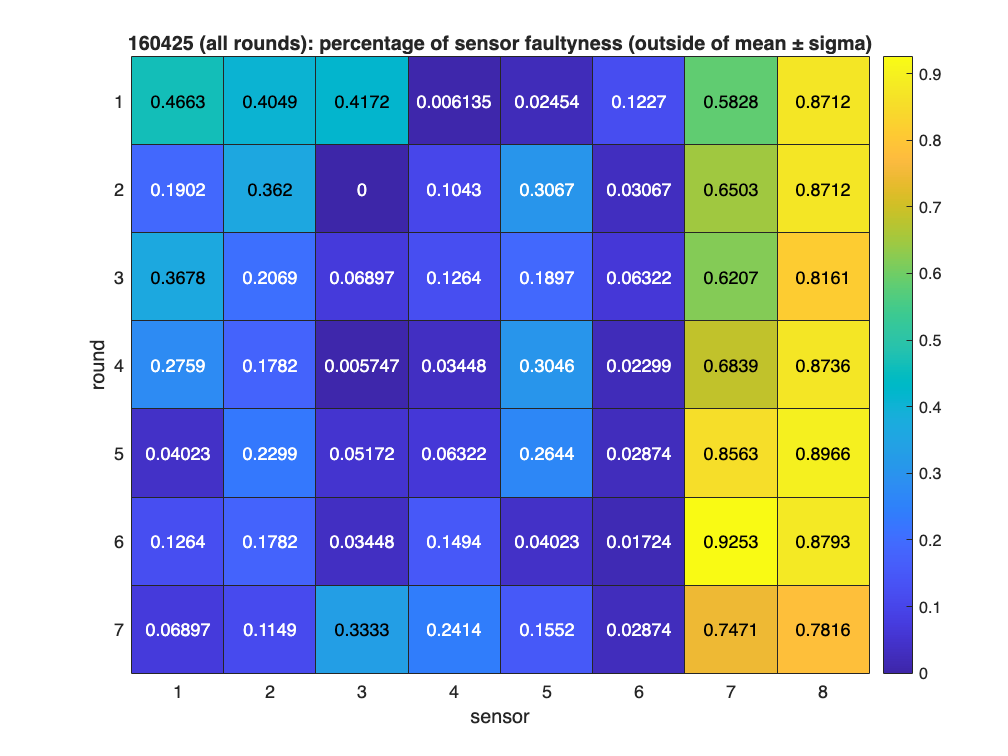

for r = 1:n_rounds
    round = "round" + r;

    pltData     = data(data.round == r & data.inj_type == 1, :);  
    plttgLength = height(pltData);

    sensor_groups = {[1 3 5 7], [2 4 6 8]}; sensor_groups_names = {"specific", "unspecific"};
    for g = 1:2
        sensor_idx = sensor_groups{g};
        data_group = zeros(plttgLength, numel(sensor_idx));

        for k = 1:numel(sensor_idx)
            s = sensor_idx(k);
            posStrVal = pltData{1, s+4};
            data_group(:, k) = pltData{:, s+4} - posStrVal;
        end

        y_std   = std(data_group, 0, 2);  % std dev
        y_mean  = mean(data_group, 2); % mena

        std_values{g} = y_std;
        mean_values{g} = y_mean;
    end

    for s = 1:n_sensors
        sensor      = "sensor" + s; 
        sensor_name = pltData.Properties.VariableNames{s+4};

        posStrVal    = pltData{1, s+4};
        rel_signal   = pltData{:, s+4} - posStrVal;

        if ismember(s, sensor_groups{1})
            g = 1;
        elseif ismember(s, sensor_groups{2})
            g = 2;
        end
        group_mean   = mean_values{g};
        group_sigma  = std_values{g};

        faulty_sensor_struct(r,s).round       = round;
        faulty_sensor_struct(r,s).sensor      = sensor;
        faulty_sensor_struct(r,s).name        = sensor_name;
        faulty_sensor_struct(r,s).isFaultyLo  = rel_signal < (group_mean - group_sigma);
        faulty_sensor_struct(r,s).isFaultyHi  = rel_signal > (group_mean + group_sigma);
        faulty_sensor_struct(r,s).isFaultyTot = faulty_sensor_struct(r,s).isFaultyLo + faulty_sensor_struct(r,s).isFaultyHi;
    end
end

outlier_matrix = zeros(7, 8);  % oder size(sensor_results)
for r = 1:7
    for s = 1:8
        outlier_matrix(r, s) = ( sum(faulty_sensor_struct(r, s).isFaultyTot) / length(faulty_sensor_struct(r, s).isFaultyTot) );
    end
end

heatmap(outlier_matrix); colormap('parula'); title(shortFileId + " (all rounds): percentage of sensor faultyness (outside of mean ± sigma)"); xlabel("sensor"); ylabel("round");

We now want to analyize the differential signals. Therefore we'll subtract the mean of the unspecific sensors from each sensor. We marked the preasumably "faulty" sensors

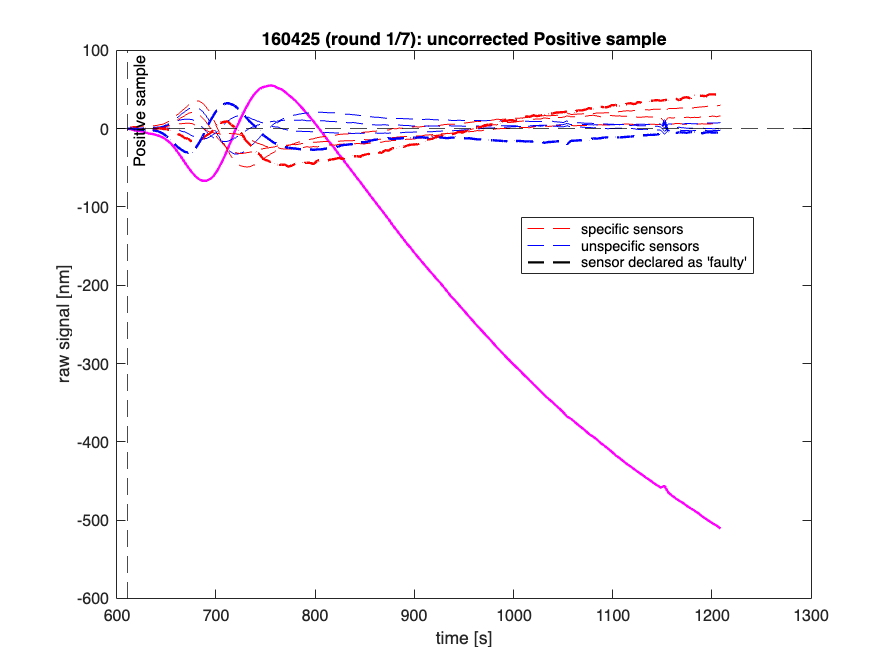

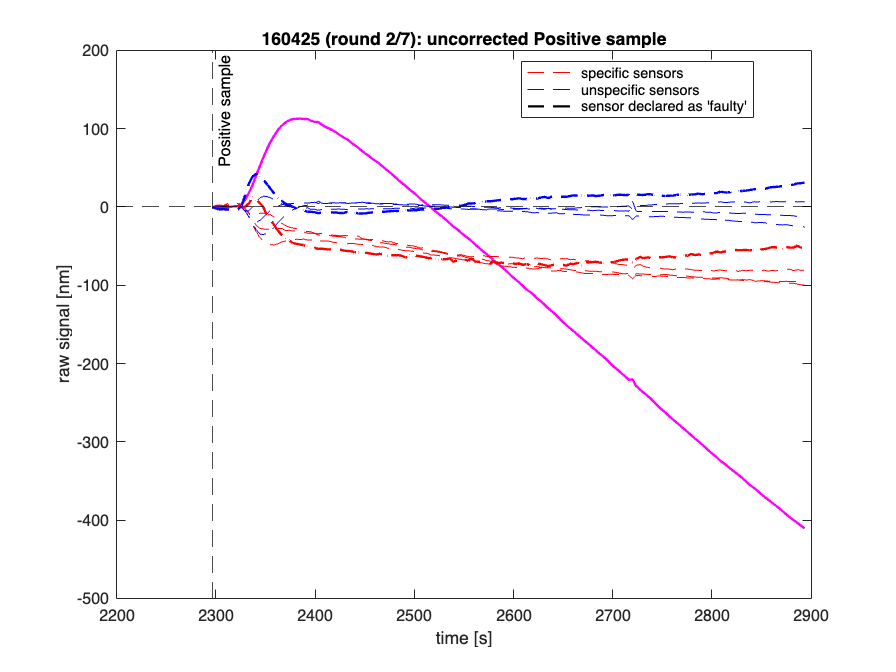

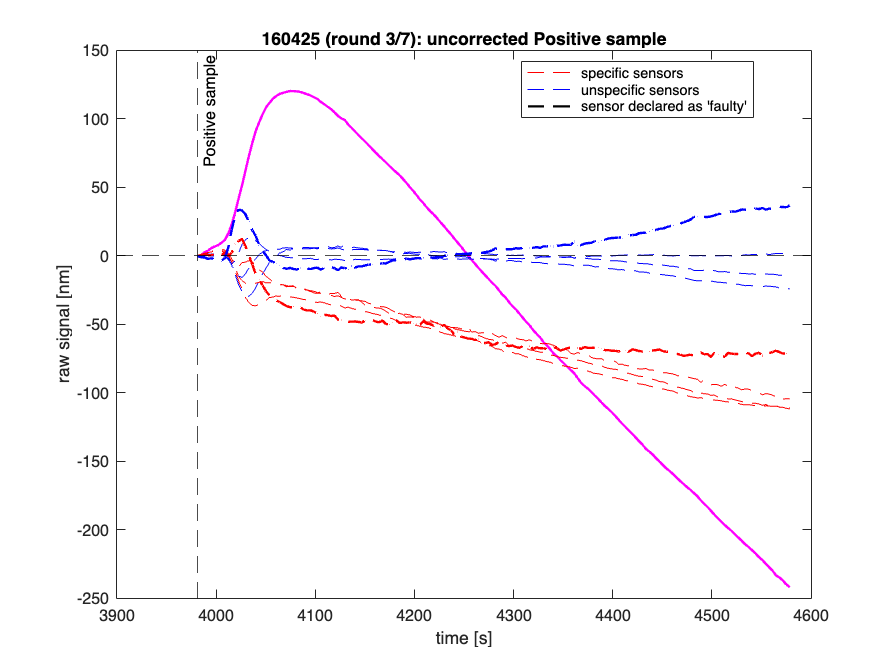

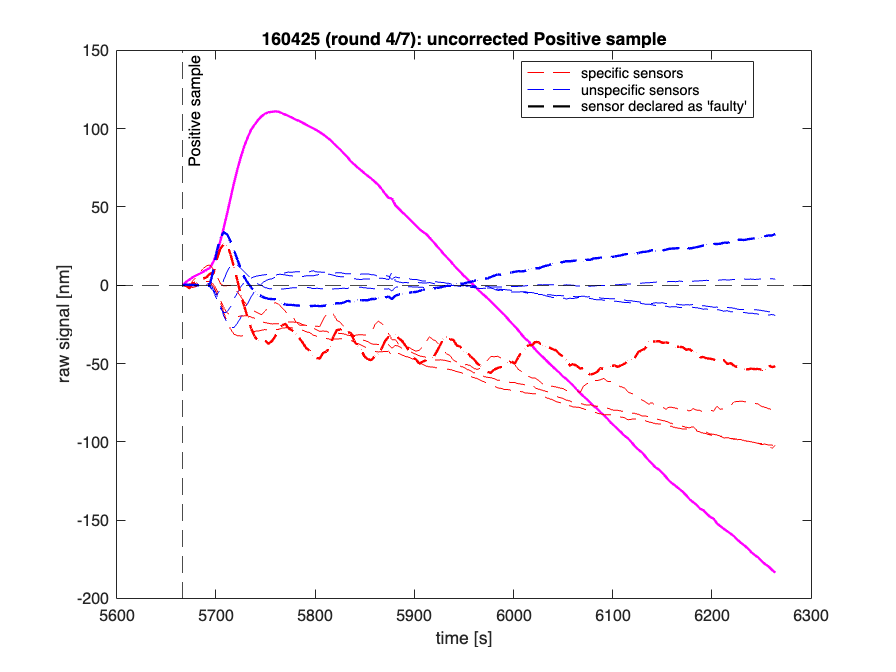

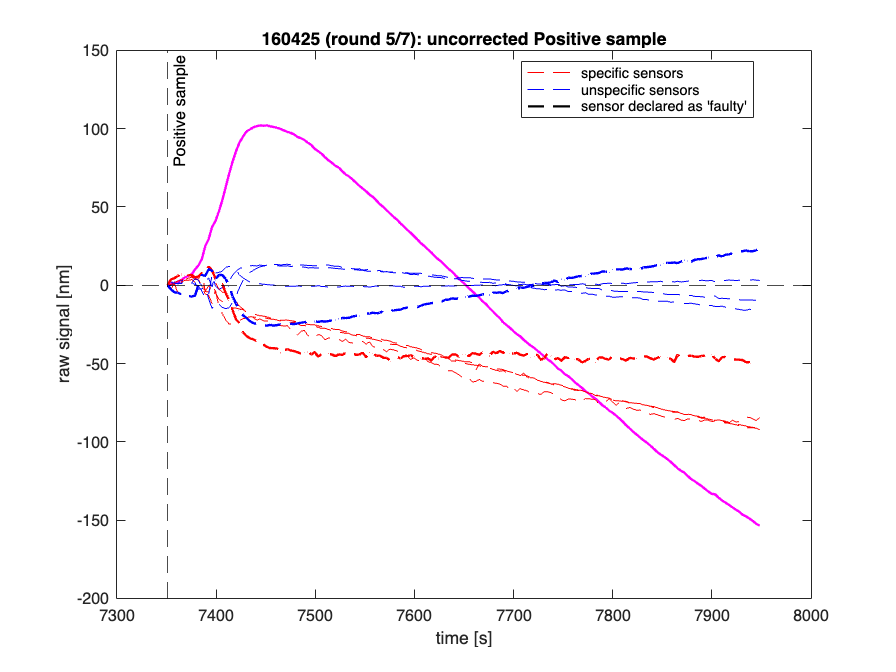

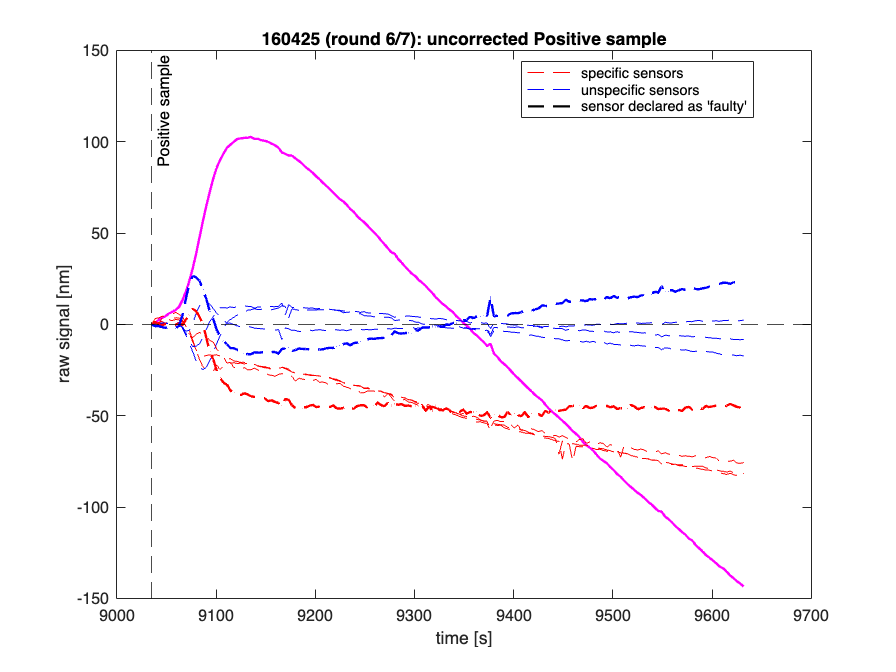

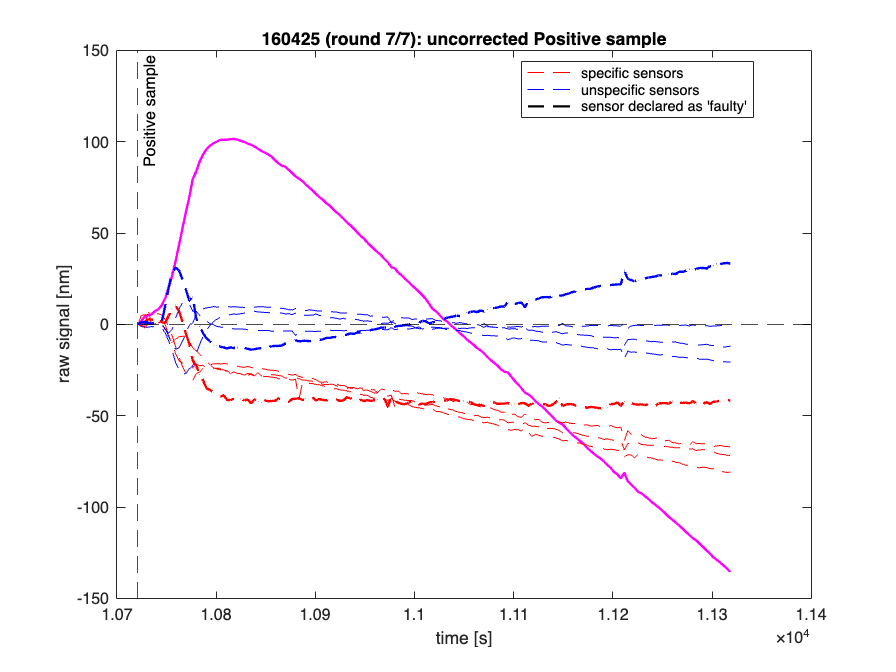

colmap = repmat([1 0 0; 0 0 1], d.meta.n_sensors, 1);
faulty_sensors = [7, 8];

for r = 1:n_rounds
    round = "round" + r;

    clf(figure(r));             % clear figure
    H{r}        = figure(r);    % create figure for round
    fig_handles = [];           % create empty array for handles
    
    % load data
    pltData     = data(data.round == r & data.inj_type == 1, :);  
    plttgLength = height(pltData);

    sensor_groups = {[1 3 5 7], [2 4 6 8]}; sensor_groups_names = {"specific", "unspecific"}; colors_fill = [1 .7 .7; .7 .7 1];

    mu_array    = mean([pltData{:, sensor_groups{2} + 4}], 2); % mean of unspecific sensors

    for g = 1:2
        sensor_idx = sensor_groups{g};
        data_group = zeros(plttgLength, numel(sensor_idx));

        for k = 1:numel(sensor_idx)
            s = sensor_idx(k);
            posStrVal = pltData{1, s+4};
            data_group(:, k) = pltData{:, s+4} - posStrVal;
        end

        y_min = min(data_group, [], 2);
        y_max = max(data_group, [], 2);
        y_std = std(data_group, 0, 2);  % std dev
        y_mean = mean(data_group, 2); % median
        t = pltData.T_s_;

        % fill([t; flipud(t)], [y_min - y_std; flipud(y_max + y_std)], colors_fill(g, :), FaceAlpha = 0.5, EdgeColor = 'none'); hold on;
        % fill([t; flipud(t)], [y_median - y_std; flipud(y_median + y_std)], colors_fill(g, :), FaceAlpha = 1, EdgeColor = 'none');

        range_values{g} = y_max - y_min;
        std_values{g} = y_std;
        mean_values{g} = y_mean;
    end

%    plot(pltData{:, "T_s_"}, mean_values{2}, Color = 'm', LineStyle = '-', LineWidth = 1.5, Marker = 'none'); hold on;
    
    for s = 1:n_sensors
        sensor      = "sensor" + s; 
        sensor_name = pltData.Properties.VariableNames{s+4} + " - mean(unspecific sensors)";

        posStrVal   = pltData{1, s+4} - mu_array(1);
        
        % plot uncorr data - unspecific sensor mean
        if ismember(s, faulty_sensors)
            plot(pltData{:, "T_s_"}, pltData{:, s+4} - posStrVal - mu_array, Color = colmap(s, :), LineStyle = '--', LineWidth = 1.5, Marker = 'none', DisplayName = sensor_name + ": uncorrected data"); hold on;
        else
            plot(pltData{:, "T_s_"}, pltData{:, s+4} - posStrVal - mu_array, Color = colmap(s, :), LineStyle = '--', Marker = 'none', DisplayName = sensor_name + ": uncorrected data"); hold on;
        end
    end

    % fig handles
    hp1 = plot(NaN, NaN, Color = colmap(1, :), LineStyle = '--', Marker = 'none', DisplayName = "specific sensors");
    hp2 = plot(NaN, NaN, Color = colmap(2, :), LineStyle = '--', Marker = 'none', DisplayName = "unspecific sensors");
    hpf = plot(NaN, NaN, Color = 'k', LineStyle = '--', LineWidth = 1.5, Marker = 'none', DisplayName = "sensor declared as 'faulty'");
    %hpm = plot(NaN, NaN, Color = 'm', LineStyle = '-', LineWidth = 1.5, Marker = 'none', DisplayName= "mean unspecific sensors");
    fig_handles = [fig_handles hp1 hp2 hpf];

    yline(0, Color = 'k', LineStyle = '--', HandleVisibility = 'off'); % add 0 base line
    xline(pltData.T_s_(1), Color = 'k', LineStyle = '--', HandleVisibility = 'off', Label = GetInjectionType(1));
    ylabel("raw signal [nm]");

    %yyaxis right;
    % for g = 1:2
    %     h = plot(pltData.T_s_, range_values{1, g}, Color = colmap(g, :), LineStyle = '-', DisplayName = "range " + sensor_groups_names{g} + " sensors");     
    %     fig_handles = [fig_handles h];
    % end
    
    % h = plot(pltData.T_s_, abs(median_values{1, 1}-median_values{1, 2}), Color = 'k', LineStyle = '-', DisplayName = "diff in median");
    % fig_handles = [fig_handles h];

    title(shortFileId + " (round " + r + "/" + n_rounds + "): uncorrected " + GetInjectionType(1) );
    xlabel("time [s]");
    legend(fig_handles, Location = 'best'); hold off;
end